clear all
load TR4_data.mat
S=[[5.7426 4 -2.4142]',[9.0487 5.5871 2.7189]'];

[Ql,Tl,Xl]=TR4_linearMov(S,@Cicloidale,5,link);

ans = 2

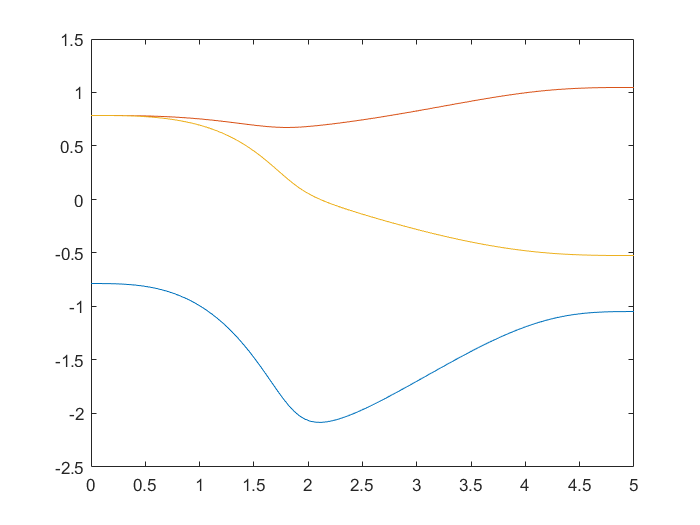

plot(Tl,Ql(1,:,1),Tl,Ql(1,:,2),Tl,Ql(1,:,3))

Q1=TR4_invNumeric(S(:,1)',[0.5 0.5 0.5],link,1000);
Q2=TR4_invNumeric(S(:,2)',[0.5 0.5 0.5],link,1000);
Q=[Q1,Q2]

Q =    -0.7854   -1.0472
    0.7854    1.0472
    0.7854   -0.5236


[X,T,Qj] = TR4_jointMov(Q,@Cicloidale,5,link);

ans = 2

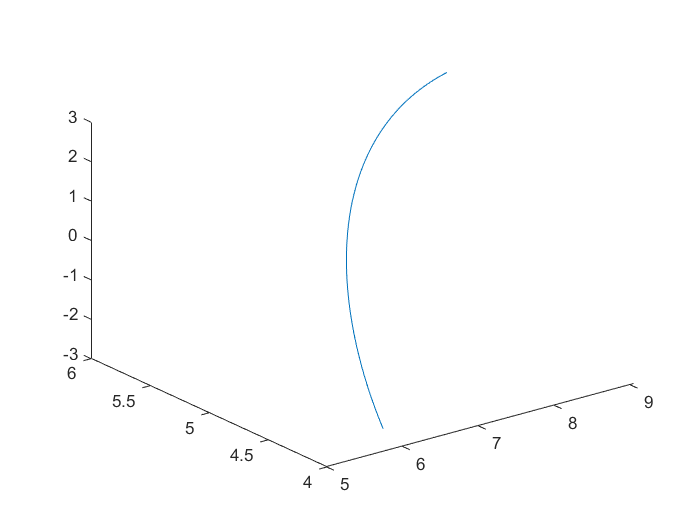

plot3(X(1,:,1),X(1,:,2),X(1,:,3))

save traiettoria_test X Ql T Q S